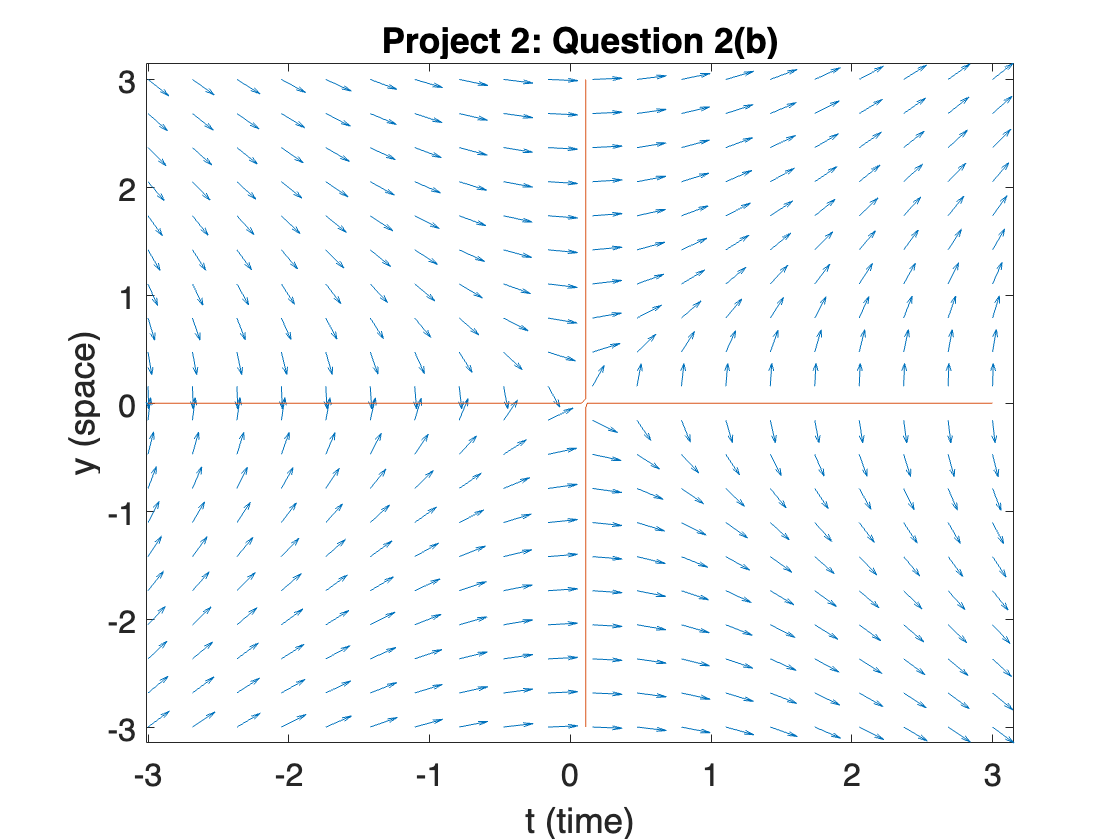

clear all % clear all variables in the workspace
set(0, 'DefaultAxesFontSize', 16) % increase font size in our figure

% define rate function using componentwise arithmetic
f = @(y,t) (3.*t.*exp(2))./(3.*y.*exp(2)-2);

% define grid for direction field
[T,Y] = meshgrid(linspace(-3,3,20),linspace(-3,3,20));

% if you want to see what meshgrid is doing
%figure;
%plot(T,P,'o')

% calculate slope (p'(t)) at each point in our grid
F = f(Y, T);

% normalize arrows to length 1
L = sqrt(1 + F.^2);

% At each point (T,P), draw the unit vector (1/L,F/L) and scale by 0.5
figure;
quiver(T, Y, 1./L, F./L,0.5)
hold on

fimplicit(f,[-3 3 -3 3])

% label axes
axis tight
xlabel('t (time)')
ylabel('y (space)')
title('Project 2: Question 2(b)')